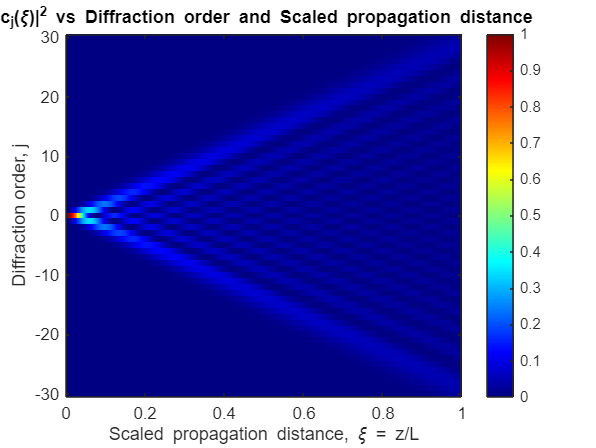

% II c

% Parameters
eta = 10 * pi;   
j_max = 30;     
xi_vals = linspace(0, 1, 1000);  
j_vals = -j_max:j_max;           

cj_squared = zeros(length(j_vals), length(xi_vals));

% Propagation loop
for j = -j_max:j_max
    for xi_idx = 1:length(xi_vals)
        xi = xi_vals(xi_idx);
        cj = besselj(j, eta * xi);  
        cj_squared(j + j_max + 1, xi_idx) = abs(cj)^2; 
    end
end

% Plotting
figure;
imagesc(xi_vals, j_vals, cj_squared);  
colormap('jet');                      
colorbar;                             
xlabel('Scaled propagation distance, \xi = z/L');
ylabel('Diffraction order, j');
title('|c_j(\xi)|^2 vs Diffraction order and Scaled propagation distance');
axis tight;                           
set(gca, 'YDir', 'normal');          

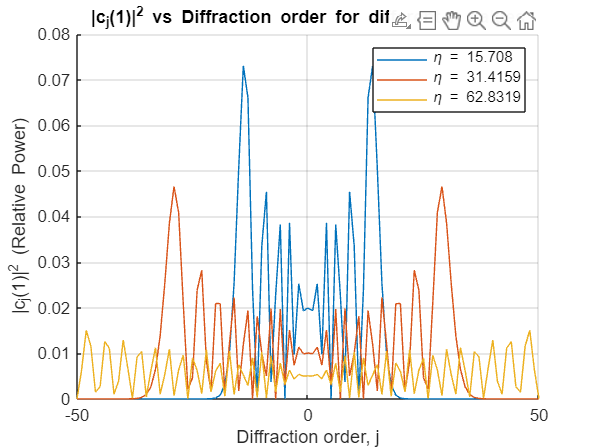

% II d

% Parameters
eta_vals = [5 * pi, 10 * pi, 20 * pi];   
j_max = 50;                              
j_vals = -j_max:j_max;                   


cj_squared_at_output = zeros(length(j_vals), length(eta_vals));

% Propagation loop
for eta_idx = 1:length(eta_vals)
    eta = eta_vals(eta_idx);
    for j = -j_max:j_max
        cj = besselj(j, eta);   
        cj_squared_at_output(j + j_max + 1, eta_idx) = abs(cj)^2;  
    end
end

% Plotting
figure;
hold on;
for eta_idx = 1:length(eta_vals)
    plot(j_vals, cj_squared_at_output(:, eta_idx), 'DisplayName', ['\eta = ', num2str(eta_vals(eta_idx))]);
end
hold off;
xlabel('Diffraction order, j');
ylabel('|c_j(1)|^2 (Relative Power)');
title('|c_j(1)|^2 vs Diffraction order for different \eta values');
legend('show');
grid on;


% Estimates
j_peak_estimates = eta_vals / pi;  
disp('Estimated peak diffraction orders (j_peak):');

Estimated peak diffraction orders (j_peak):


disp(j_peak_estimates);

     5    10    20

